SSclc;
clear;
Tuning2 = load("CalibrationDataFixed1.mat");
Tuning2 = Tuning2.data;


% Torques calculated via force plate forces using the jacobian, 
% lets try use x y forces to match force plate


FPy = [];
FPz = [];
MRq = [];
MLq = [];
MRt_read = [];
MLt_read = [];
MRt_cmd = [];
MLt_cmd = [];
ts = 1000;
times1 = [13.7, 21.8; % remove outliers (current reading glitch)
            22.6, 34.3;
            35, 55.4];
times = [13.5, 55.4;
    13.7, 47.9;
    13.7, 63;
    16.2, 66.2;
    13.6, 62];
KPs = [1000; 1250; 1500; 1750; 2000];
for i = 1:3
    FPy = [FPy; Tuning2{1}{2}.Values.Data(times1(i, 1)*ts: times1(i, 2)*ts)];
    FPz = [FPz; Tuning2{1}{3}.Values.Data(times1(i, 1)*ts: times1(i, 2)*ts)];
    % Motor angles
    MR_resample = resample(Tuning2{1}{11}.Values.q, Tuning2{1}{1}.Values.Time);
    MRq = [MRq; MR_resample.Data(times1(i, 1)*ts: times1(i, 2)*ts)];
    ML_resample = resample(Tuning2{1}{12}.Values.q, Tuning2{1}{1}.Values.Time);
    MLq = [MLq; ML_resample.Data(times1(i, 1)*ts: times1(i, 2)*ts)];
    
    % Motor torques (read)
    MR_resample = resample(Tuning2{1}{11}.Values.t, Tuning2{1}{1}.Values.Time);
    MRt_read = [MRt_read; MR_resample.Data(times1(i, 1)*ts: times1(i, 2)*ts)];
    ML_resample = resample(Tuning2{1}{12}.Values.t, Tuning2{1}{1}.Values.Time);
    MLt_read = [MLt_read; ML_resample.Data(times1(i, 1)*ts: times1(i, 2)*ts)];
end
for i = 2:5
    % Force plate

    FPy = [FPy; Tuning2{i}{2}.Values.Data(times(i, 1)*ts: times(i, 2)*ts)];
    FPz = [FPz; Tuning2{i}{3}.Values.Data(times(i, 1)*ts: times(i, 2)*ts)];
    % Motor angles
    MR_resample = resample(Tuning2{i}{11}.Values.q, Tuning2{i}{1}.Values.Time);
    MRq = [MRq; MR_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];
    ML_resample = resample(Tuning2{i}{12}.Values.q, Tuning2{i}{1}.Values.Time);
    MLq = [MLq; ML_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];

    % Motor torques (read)
    MR_resample = resample(Tuning2{i}{11}.Values.t, Tuning2{i}{1}.Values.Time);
    MRt_read = [MRt_read; MR_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];
    ML_resample = resample(Tuning2{i}{12}.Values.t, Tuning2{i}{1}.Values.Time);
    MLt_read = [MLt_read; ML_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];

end
clear MR_resample ML_resample


## Transfer force plate data into torques

% From the side of forces:

Fy_read = [];
Fz_read = [];
FP_tl = [];
FP_tr = [];
[J11, J12, J21, J22] = BalekaJacobianXY(MLq, MRq);
for i = 1:length(FPz)
    Jxy = [J11(i), J12(i); J21(i), J22(i)];
    JTxy = Jxy';

    F_read = JTxy\[MLt_read(i)*9*0.198; MRt_read(i)*9*0.198];
    Fy_read = [Fy_read; -F_read(1)];
    Fz_read = [Fz_read; -F_read(2)];
end
clear F_cmd F_read i J11 J12 J22 J21 times ts JTxy Jxy


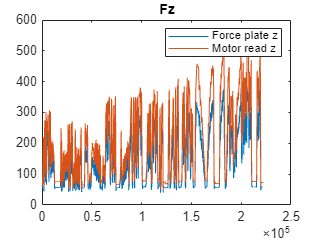

% forces:
plot(FPz)
hold on
plot(Fz_read)
legend('Force plate z', 'Motor read z');
title('Fz')
hold off


errFzRead = mean((Fz_read - FPz).^2)

errFzRead = 4.5631e+03


plot(FPy)
hold on
plot(Fy_read)
legend('Force plate y','Force plate Horizontal', 'Motor read Fy');

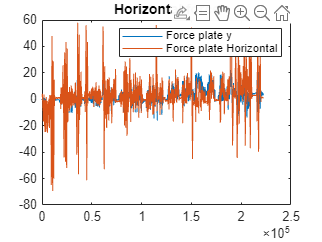

title('Horizontal force')
hold off

errFxyRead = mean((Fy_read - FPy).^2)

errFxyRead = 78.0337

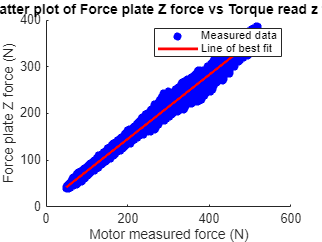

% Z force

[coeff, Sr] = polyfit(Fz_read, FPz, 1);
xFit = linspace(min(Fz_read), max(Fz_read), 1000);
yFit = polyval(coeff, xFit);

scatter(Fz_read, FPz, 'b','filled')
hold on
plot(xFit, yFit, 'r-', LineWidth=2)
title("Scatter plot of Force plate Z force vs Torque read z force");
ylabel("Force plate Z force (N)");
xlabel("Motor measured force (N)");
legend("Measured data", "Line of best fit")
hold off

m1 = coeff(1)

m1 = 0.6876

c1 = coeff(2)

c1 = 8.0238

R1 = Sr.rsquared

R1 = 0.9930

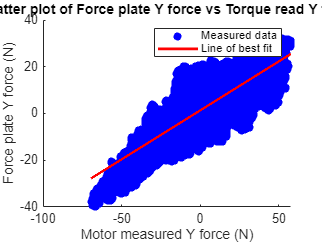

%where line of best fit is y=mx +c

% Y force
[coeff, Sr] = polyfit(Fy_read, FPy, 1);
xFit = linspace(min(Fy_read), max(Fy_read), 1000);
yFit = polyval(coeff, xFit);

scatter(Fy_read, FPy, 'b','filled')
hold on
plot(xFit, yFit, 'r-', LineWidth=2)
title("Scatter plot of Force plate Y force vs Torque read Y force");
ylabel("Force plate Y force (N)");
xlabel("Motor measured Y force (N)");
legend("Measured data", "Line of best fit")
hold off

m2 = coeff(1)

m2 = 0.4188

c2 = coeff(2)

c2 = 1.3050

R2 = Sr.rsquared

R2 = 0.5769

Rsq = corrcoef(FPy, Fy_read).^2

Rsq =     1.0000    0.5769
    0.5769    1.0000


%where line of best fit is y=mx +c